% 旋转攻击
function rotationattack_img = rotationattack(img, angle)
    % J = imrotate(I, angle, method, bbox)
    % method是文本字符串，需要引号引出，method包括：
    % 'nearest' - 最临近插值（默认值）
    % 'bilinear' - 双线性插值
    % 'bicubic' - 双三次插值
    % bbox是文本字符串，需要引号引出，bbox包括：
    % 'crop' - 输出的图像B和输入的图像A保持一致的尺寸，裁剪旋转的图像至合适的大小
    % 'loose' - 输出足够容纳整个旋转图像的图像B，图像B通常比图像A大（默认值）
    rotationattack_img = imrotate(img, angle, 'bicubic', 'crop'); % 此函数将图像I围绕其中心点逆时针方向旋转angle度
end
% 加载原始图像
original_image = imread('lena256.bmp');

% 旋转攻击
angle = 10; % 旋转角度
rotated_image = rotationattack(original_image, angle);

% 剪切攻击
percentage = 0.2; % 剪切比例
cropped_image = edgeattack(original_image, percentage);

% 显示结果
figure;
subplot(1, 3, 1);
imshow(original_image);
title('原始图像');

subplot(1, 3, 2);
imshow(rotated_image);
title('旋转攻击后的图像');

subplot(1, 3, 3);
imshow(cropped_image);
title('剪切攻击后的图像');




clear
close all

I=imread('水印.png');

ans =     68    70     3


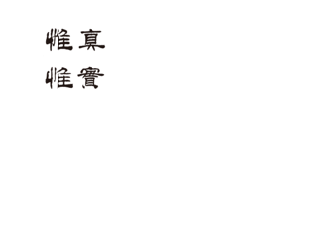

J=double(imresize(J,[64,64]));
% I=rgb2gray(Y1);

subplot(2,3,1);%将彩色图像变成灰度图像

imshow(I);

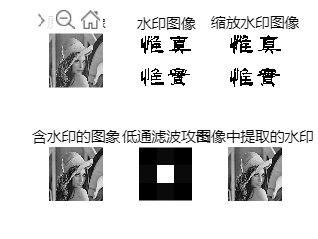


size=512; N=32;K=8; D=zeros(size);E=0.01;

I=imread('lena.jpg');

% I=rgb2gray(Y1);

subplot(2,3,1);%将彩色图像变成灰度图像

imshow(I);

title('原始图像');

I=double(I)/512;%读入水印

J=imread('水印(二值).bmp');

subplot(2,3,2);

imshow(J);

title('水印图像');

%对水印缩放

J=double(imresize(J,[64,64]));

subplot(2,3,3);

imshow(J);

title('缩放水印图像');

%嵌入水印

for p=1:size/K %为待嵌入水印的变换域的行坐标

for q=1:size/K

x=(p-1)*K+1; y=(q-1)*K+1;

I_dct=I(x:x+K-1,y:y+K-1);%将原图分成8*8的子块

I_dct1=dct2(I_dct);%对子块进行DCT变换

if J(p,q)==0

alfa=0;

else

alfa=0.05;

end

I_dct2=I_dct1+alfa*E;

I_dct=idct2(I_dct2);

D(x:x+K-1,y:y+K-1)=I_dct;

end

end

subplot(2,3,4);

imshow(D,[]);

title('含水印的图象');

%%%%%%对加入水印的图像进行各种攻击

%%%低通滤波攻击

% hh=fspecial('gaussian',3,0.1);

%hh=fspecial('gaussian',3,0.35);
 hh=fspecial('gaussian',3,0.4);

QQ=filter2(hh,D);

% 提取水印

for p=1:size/K

for q=1:size/K

x=(p-1)*K+1;

y=(q-1)*K+1;

I1=I(x:x+K-1,y:y+K-1);

I2=QQ(x:x+K-1,y:y+K-1);

I_dct1=dct2(I1);

I_dct2=dct2(I2);

if I_dct2>I_dct1

W(p,q)=1;

else

W(p,q)=0;

end

end

end

subplot(2,3,5);imshow(hh,[]);title('低通滤波攻击');

subplot(2,3,6);imshow(QQ,[]);title('图像中提取的水印');